smallTracks = readtable('smallTracksShuffled.csv');
numPCA = 200;
numSongs = 500;
trainVectors = zeros(numPCA, numSongs);
genres = {};
songsPerGenre = {};
for i=1:numSongs
    trainVectors(:,i) = songToVector(getTrackFilePathFromID(smallTracks(i,:).Var1),numPCA);
    genreIndex = find([genres{:}] == smallTracks(i,:).genreID);
    if isempty(genreIndex)
        genres = [genres, smallTracks(i,:).genreID];
        genreIndex = size(genres,2);
        songsPerGenre{genreIndex} = [];
    end
    songsPerGenre{genreIndex} = [songsPerGenre{genreIndex}, trainVectors(:,i)];
end

save('smallTrackTrained')

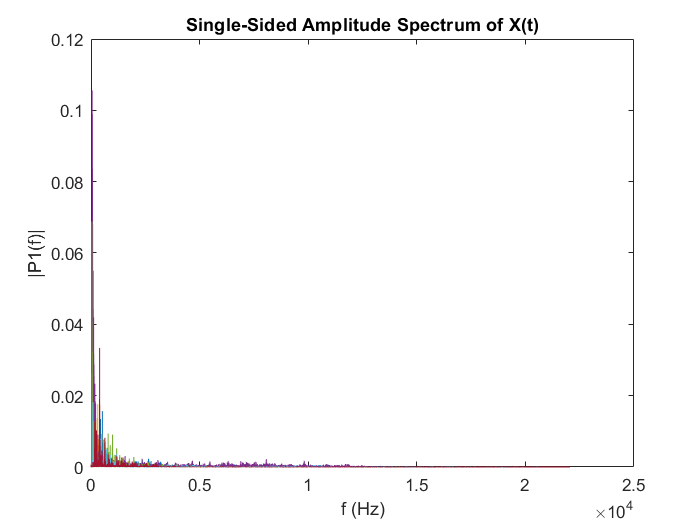


R = cov(trainVectors'); %note transpose
dimensions = 200; %number of eigensongs to define songSpace with
[V, D] = eigs(R, dimensions);
numGenres = size(songsPerGenre,2);

thresholds = zeros(1, numGenres);
genreAveMatrix = zeros(numPCA, numGenres);
for i=1:numGenres
    [genreAveMatrix(:,i), thresholds(i)] = getGenreClass(songsPerGenre{i});
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Identify Genre of unknown song
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Get test song
randomSongID = randi([numSongs,size(smallTracks,1)-numSongs]);
testSong = getTrackFilePathFromID(smallTracks(randomSongID,:).Var1);
[data, Fs] = audioread(testSong); %Fs is the sampling frequency

% Use FFT to get power-spectral density
fHat = fft(data);
fileLength = length(fHat(:,1));  % Length of signal

% Get one-sided PSD
P2 = abs(fHat/fileLength);
P1 = P2(1:fileLength/2 + 1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(fileLength/2))/fileLength; %frequencies

%plot PSD
plot(f,P1) 
hold on
title('Single-Sided Amplitude Spectrum of X(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

testSongFreqs = songToVector(testSong,numPCA)';
test_song = V' * testSongFreqs;

% Calculate distance to closest genre
closestDist  = intmax; %start as large as possible
closestIndex = -1 %set to -1 to throw error if not changed

closestIndex = -1

for index = 1:numGenres
    GenreAve = genreAveMatrix(index);
    distToGenre = edist(test_song, GenreAve)
    if distToGenre < closestDist
        closestDist  = distToGenre;
        closestIndex = index;
    end
end

distToGenre = 5.4608e+03

distToGenre = 5.4575e+03

distToGenre = 5.4806e+03

distToGenre = 5.4976e+03

distToGenre = 5.4486e+03

distToGenre = 5.4808e+03

distToGenre = 5.4581e+03

distToGenre = 5.5204e+03


% Check if member of genre and return
if closestDist < thresholds(closestIndex)
    closestIndex
    genres{closestIndex}                  
    smallTracks(randomSongID,:).genreID
else
    "new genre"
end

closestIndex = 5

ans = 12

ans = 17

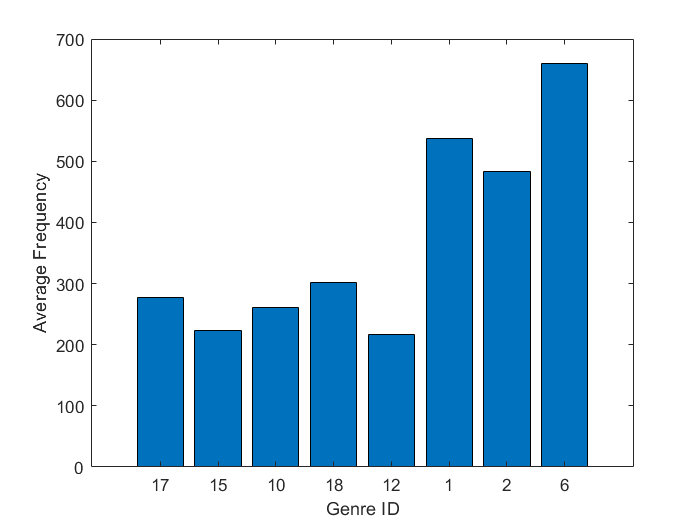

genreAverages = zeros(1, numGenres);
for index = 1:numGenres
    genreAverages(index) = mean(songsPerGenre{index}, 'all');
end
clf
bar(genreAverages)
set(gca,'xticklabel',genres)
xlabel('Genre ID')
ylabel('Average Frequency')